# Assignment 3

**Dynamical Systems and Non-Linear Dynamics**

**Giorgia Del Missier – i6292403**

## Chaos in a three-species food chain

a) Using parameter values a1=5, b1=3, a2=0.1, b2=2, d1=0.4, d2=0.01, illustrate that the system exhibits deterministic chaos:

- Trajectories are aperiodic and bounded

- There is sensitive dependence on initial conditions

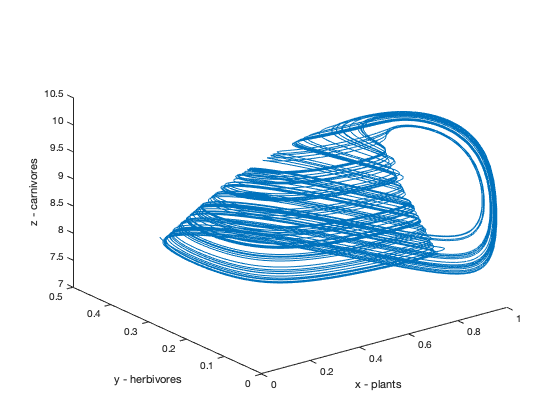

a1 = 5;
b1 = 3;
a2 = 0.1;
b2 = 2;
d1 = 0.4;
d2 = 0.01;

xHandle = @(x, y, z) x.*(1-x)-((a1.*x)./(1+b1.*x)).*y;
yHandle = @(x, y, z) ((a1.*x)./(1+b1.*x)).*y-d1.*y-((a2.*y)./(1+b2.*y)).*z;
zHandle = @(x, y, z) ((a2.*y)./(1+b2.*y)).*z-d2.*z;

hastingspowell = @(t, x) [...
    xHandle(x(1), x(2), x(3));...
    yHandle(x(1), x(2), x(3));...
    zHandle(x(1), x(2), x(3))];

%% Simulation
x0 = [0.2, 0.4, 8];
tStable = 3000;

[tSolution0, xSolution0] = ode45(hastingspowell, 0:0.01:tStable, x0);

x1 = x0 + 10^-10;
[tSolution1, xSolution1] = ode45(hastingspowell, 0:0.01:tStable, x1);

x2 = x0 - 10^-15;
[tSolution2, xSolution2] = ode45(hastingspowell, 0:0.01:tStable, x2);

figure();
plot3(xSolution0(:, 1), xSolution0(:, 2), xSolution0(:, 3));
view(3);
xlabel('x - plants');
ylabel('y - herbivores');
zlabel('z - carnivores');
rotate3d on;

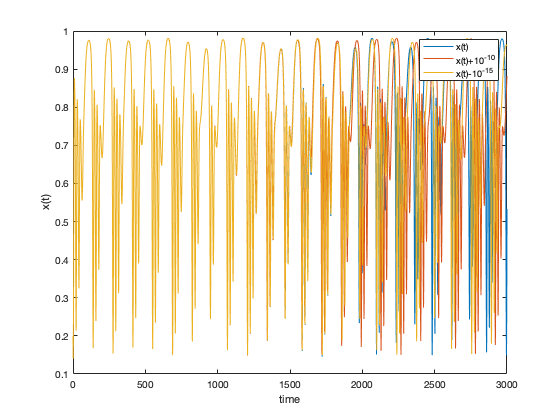

figure()
plot(tSolution0, xSolution0(:, 1));
xlabel('time');
ylabel('x(t)');
hold on
plot(tSolution1, xSolution1(:, 1))
plot(tSolution2, xSolution2(:, 1))
legend({'x(t)', 'x(t)+10^{-10}', 'x(t)-10^{-15}'});
xlim([0 3000])
hold off

The figure above illustrates how in the system there is sensitive dependence on initial conditions, which even though they start at very close points tend in the long term to diverge exponentially: this is a clear signature of the presence of a strange attractor in the system and of occurrence of deterministic chaos.

b) Compute the Liapunov exponent of the model for the parameter values given above. What is the value (and sign) of λ and what does it tell us about the strange attractor?

a1 = 5;
b1 = 3;
a2 = 0.1;
b2 = 2;
d1 = 0.4;
d2 = 0.01;

xHandle = @(x, y, z) x.*(1-x)-((a1.*x)./(1+b1.*x)).*y;
yHandle = @(x, y, z) ((a1.*x)./(1+b1.*x)).*y-d1.*y-((a2.*y)./(1+b2.*y)).*z;
zHandle = @(x, y, z) ((a2.*y)./(1+b2.*y)).*z-d2.*z;

hastingspowell = @(t, x) [...
    xHandle(x(1), x(2), x(3));...
    yHandle(x(1), x(2), x(3));...
    zHandle(x(1), x(2), x(3))];

% Simulation
x0 = [0.2, 0.4, 8];
tTransient =1000;
tStable = 5000;

[tInitial, xInitial] = ode45(hastingspowell, [0, tTransient], x0);

[tSolution1, xSolution1] = ode45(hastingspowell, 0:0.01:tStable, xInitial(end, :));

x2 = xInitial(end, :) + 10^-15;
[tSolution2, xSolution2] = ode45(hastingspowell, 0:0.01:tStable, x2);

d = sqrt((xSolution1(:, 1) - xSolution2(:, 1)).^2 + (xSolution1(:, 2) - xSolution2(:, 2)).^2 + (xSolution1(:, 3) - xSolution2(:, 3)).^2);
index = find(tSolution1 == 1000);
lm = fitlm(tSolution1(1:index, :),log(d(1:index, :)));
betahat=lm.Coefficients.Estimate(2)

betahat = 0.0323

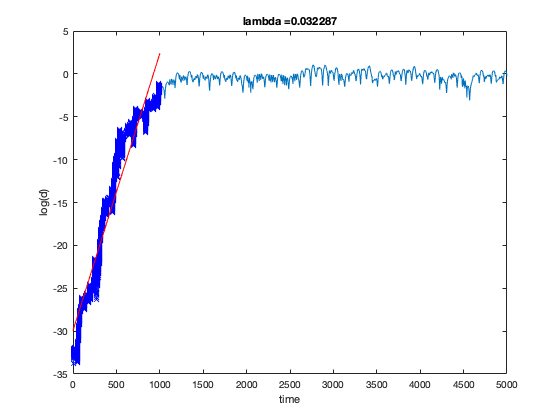

figure()
plot(tSolution1, log(d))
hold on
plot(lm)
xlabel('time');
ylabel('log(d)');
title(strcat('lambda = ',num2str(betahat)))
legend off
hold off

lambdas = [];

for i = 1:10
    x0 = [rand * 10, rand * 15, rand * 5];
    tTransient =1000;
    tStable = 5000;

    [tInitial, xInitial] = ode45(hastingspowell, [0, tTransient], x0);

    [tSolution1, xSolution1] = ode45(hastingspowell, 0:0.01:tStable, xInitial(end, :));

    x2 = xInitial(end, :) + 10^-15;
    [tSolution2, xSolution2] = ode45(hastingspowell, 0:0.01:tStable, x2);

    d = sqrt((xSolution1(:, 1) - xSolution2(:, 1)).^2 + (xSolution1(:, 2) - xSolution2(:, 2)).^2 + (xSolution1(:, 3) - xSolution2(:, 3)).^2);
    index = find(tSolution1 == 1000);
    lm = fitlm(tSolution1(1:index, :),log(d(1:index, :)));
    betahat=lm.Coefficients.Estimate(2);
    lambdas(i) = betahat;
end

mean(lambdas)

ans = 0.0211

As indicated above, the value of lambda averaged for different initial conditions has a value of 0.02. A positive Lyapunov exponent is another signature of chaos occurrence in the system.

c) Keeping all other parameter values fixed, vary the value of the parameter b1 in the interval 2<b1<3. Starting at b1=2 find values of b1 for which there is:

- a stable fixed point

- a Hopf bifurcation to a stable oscillation

- a stable oscillation with twice the period of the previous one (period-2 rhythm)

- a period-4 rhythm

What happens next to the oscillations? Briefly explain in words how chaos can arise from such a sequence of bifurcations.

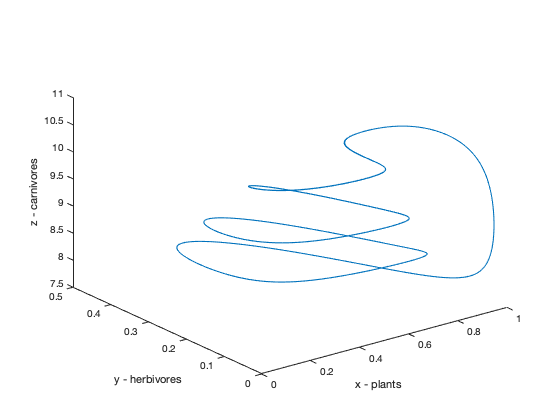

a1 = 5;
b1 = 2.91;
a2 = 0.1;
b2 = 2;
d1 = 0.4;
d2 = 0.01;

xHandle = @(x, y, z) x.*(1-x)-((a1.*x)./(1+b1.*x)).*y;
yHandle = @(x, y, z) ((a1.*x)./(1+b1.*x)).*y-d1.*y-((a2.*y)./(1+b2.*y)).*z;
zHandle = @(x, y, z) ((a2.*y)./(1+b2.*y)).*z-d2.*z;

hastingspowell = @(t, x) [...
    xHandle(x(1), x(2), x(3));...
    yHandle(x(1), x(2), x(3));...
    zHandle(x(1), x(2), x(3))];

%% Simulation
x0 = [0.2, 0.4, 8];
tTransient = 1000;
tStable = 5000;

opts = odeset('RelTol',1e-5,"AbsTol",1e-10);

[tInitial, xInitial] = ode45(hastingspowell, [0, tTransient], x0, opts);
[tSolution, xSolution] = ode45(hastingspowell, [0, tStable], xInitial(end, :), opts);

figure();
plot3(xSolution(:, 1), xSolution(:, 2), xSolution(:, 3));
view(3);
xlabel('x - plants');
ylabel('y - herbivores');
zlabel('z - carnivores');
rotate3d on;

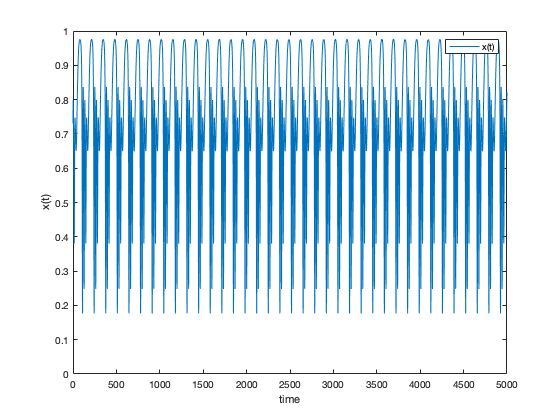

figure()
plot(tSolution, xSolution(:, 1));
xlabel('time');
ylabel('x(t)');
hold on
legend({'x(t)'});
xlim([0 5000])
ylim([0 1])
hold off

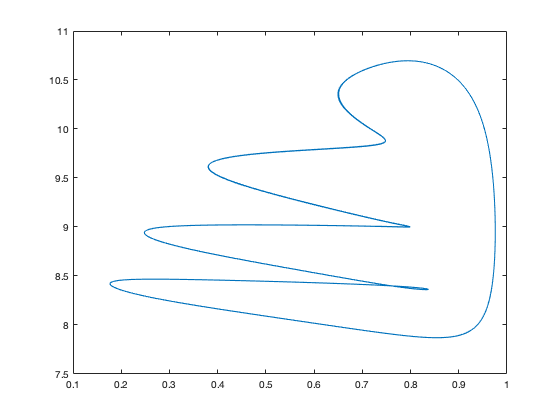

figure()
plot(xSolution(:, 1), xSolution(:, 3))

By only changing the value of b1 while keeping all the other parameter values fixed, it can be found:

- a stable fixed point at a value of b1 = 2;

- a Hopf bifurcation occurs in between values of b1 = 2.10 and b1 = 2.12; after this value a stable oscillation is visible in the three plots;

- a period 2 stable oscillation occurs at b1 = 2.31;

- a period 4 rhythm can be found at b1 = 2.91;

Next to the oscillations, the period doubling route to chaos occurs. This can also be visualized through an orbit diagram.